% Jep Brinkmann Thesis HMM example
clc; close all;
k = 4;
d = 30;
n = 5;

options.method = "random_no_offset";
options.epsilon = 1/10;

T_seq = 1e5;
m = 150;

covNorm = zeros(m, 4);
Cost = zeros(m, 4);


options.maxIter = 2500;
options.tol = 1e-14;
options.th_relerr = 1e-7;

alpha = 0.1;
rho = 0.90;


T_hats = cell(n,1);
O_hats = cell(n,1);
T_hat = zeros(k,k);

P3 = cell(n,1);



for i = progress(1:m)
    [T, O, pi, k, d] = generateHMM(k, d, n, options);
    
    cov = 0;
    
    for ii = 1:n
        cov = (1/n) * sum(corrcoef(O{ii}), "all")/(k*k);
    end

    covNorm(i, 1:2) = cov;

    [seq, ~] = generate_multivariate_hmm_sequence(T, O, pi, T_seq);
    for ii = 1:n
        P3{ii} = ProbabilityTensorGenerate(seq(ii, :), 3, d);
    end

    % Uncoupled CPD
    T_hat = zeros(k,k);
    for ii = 1:n
        [A, B, C, ~, ~] = cpd_als_3d(P3{ii}, k, options);
        O_hat = Stochasticize(B);
        T_hats{ii} = Stochasticize(pinv(Stochasticize(B)) * Stochasticize(C));
    
        Pbest = PermutationFit(T, T_hats{ii}, true);
        T_hats{ii} = Pbest * T_hats{ii} * Pbest';
        T_hat = T_hat + (1/n) * T_hats{ii};
    
        O_hats{ii} = O_hat * Pbest';
    end

    Cost(i, 1) = HMMError(T, O, T_hat, O_hats, false);  
    
    % Coupled CPD
    [T_hat, O_hats, ~, ~] = multivariate_coupled_cpd_2(P3, k, d, n, alpha, rho, options);
    pi_hat = findStationaryDistribution(T_hat')';
    [T_hat, O_hats, ~] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);

    Cost(i, 2) = HMMError(T, O, T_hat, O_hats, false);  
end

Processing:  000%  |                                      | 0/150it [00:00:00<Inf:NaN:NaN, Inf it/s]



options.method = "random";


for i = progress(1:m)
    [T, O, pi, k, d] = generateHMM(k, d, n, options);
    
    cov = 0;
    
    for ii = 1:n
        cov = (1/n) * sum(corrcoef(O{ii}), "all")/(k*k);
    end

    covNorm(i, 3:4) = cov;

    [seq, ~] = generate_multivariate_hmm_sequence(T, O, pi, T_seq);

    for ii = 1:n
        P3{ii} = ProbabilityTensorGenerate(seq(ii, :), 3, d);
    end

    T_hat = zeros(k,k);
    % Uncoupled CPD
    for ii = 1:n
        [A, B, C, ~, ~] = cpd_als_3d(P3{ii}, k, options);
        O_hat = Stochasticize(B);
        T_hats{ii} = Stochasticize(pinv(Stochasticize(B)) * Stochasticize(C));
    
        Pbest = PermutationFit(T, T_hats{ii}, true);
        T_hats{ii} = Pbest * T_hats{ii} * Pbest';
        T_hat = T_hat + (1/n) * T_hats{ii};
    
        O_hats{ii} = O_hat * Pbest';
    end

    Cost(i, 3) = HMMError(T, O, T_hat, O_hats, false);  

    % Coupled CPD

    [T_hat, O_hats, ~, ~] = multivariate_coupled_cpd_2(P3, k, d, n, alpha, rho, options);
    pi_hat = findStationaryDistribution(T_hat')';
    [T_hat, O_hats, ~] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);

    Cost(i, 4) = HMMError(T, O, T_hat, O_hats, false);  
end

Processing:  000%  |                                      | 0/150it [00:00:00<Inf:NaN:NaN, Inf it/s]



save("PerformanceTests/CorrelationPerformance", "covNorm", "Cost")


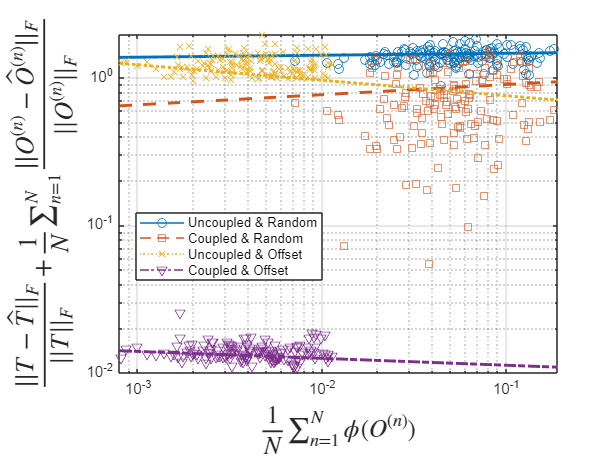


load("PerformanceTests/CorrelationPerformance");

px = [0.0008 0.19];

cmap = orderedcolors("gem");

figure()
py = polyval(polyfit(covNorm(:, 1), Cost(:, 1), 1), px);
loglog(covNorm(:,1), Cost(:, 1), 'o', 'color', cmap(1, :)); hold on;
plot(px, py, '-', 'LineWidth', 2, 'color', cmap(1, :)); hold on;

py = polyval(polyfit(covNorm(:, 2), Cost(:, 2), 1), px);
loglog(covNorm(:,2), Cost(:, 2), 's', 'color', cmap(2, :)); hold on;
loglog(px, py, '--', 'LineWidth', 2, 'color', cmap(2, :)); hold on;


py = polyval(polyfit(covNorm(:, 3), Cost(:, 3), 1), px);
loglog(covNorm(:,3), Cost(:, 3), 'x', 'color', cmap(3, :)); hold on;
loglog(px, py, ':', 'LineWidth', 2, 'color', cmap(3, :)); hold on;


py = polyval(polyfit(covNorm(:,4), Cost(:, 4), 1), px);
loglog(covNorm(:,4), Cost(:, 4), 'v', 'color', cmap(4, :)); hold on;
loglog(px, py, '-.', 'LineWidth', 2, 'color', cmap(4, :)); hold on;

grid on; xlim(px);
ylabel("$\frac{||T - \hat{T}||_F}{||T||_F} + \frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", "Interpreter","latex",'FontSize',18,'FontWeight','bold')
xlabel("$\frac{1}{N}\sum_{n=1}^N\phi(O^{(n)})$", "Interpreter","latex",'FontSize',17,'FontWeight','bold')

qw{1} = plot(nan, '-o', 'color', cmap(1, :));
qw{2} = plot(nan, '--s', 'color', cmap(2, :));
qw{3} = plot(nan, ':x', 'color', cmap(3, :));
qw{4} = plot(nan, '-.v', 'color', cmap(4, :)); 
legend([qw{:}], {"Uncoupled & Random", "Coupled & Random", "Uncoupled & Offset", "Coupled & Offset"}, 'location', 'best')


options.method = "random";

for i = progress(1:m)
    [T, O, pi, k, d] = generateHMM(k, d, n, options);
    
    cov = 0;
    
    for ii = 1:n
        cov = (1/n) * sum(corrcoef(O{ii}), "all")/(k*k);
    end

    covNorm(i, 3:4) = cov;

    [seq, ~] = generate_multivariate_hmm_sequence(T, O, pi, T_seq);

    for ii = 1:n
        P3{ii} = ProbabilityTensorGenerate(seq(ii, :), 3, d);
    end

    alpha = 0.9;
    [T_hat, O_hats, ~, ~] = multivariate_coupled_cpd(P3, k, d, n, alpha, rho, options);
    pi_hat = findStationaryDistribution(T_hat')';
    [T_hat, O_hats, ~] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);

    Cost(i, 3) = HMMError(T, O, T_hat, O_hats, false);  


    % Coupled CPD
    alpha = 0.1;
    [T_hat, O_hats, ~, ~] = multivariate_coupled_cpd_2(P3, k, d, n, alpha, rho, options);
    pi_hat = findStationaryDistribution(T_hat')';
    [T_hat, O_hats, ~] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);

    Cost(i, 4) = HMMError(T, O, T_hat, O_hats, false);  
end

Processing:  000%  |                                    | 0/1000it [00:00:00<Inf:NaN:NaN, Inf it/s]


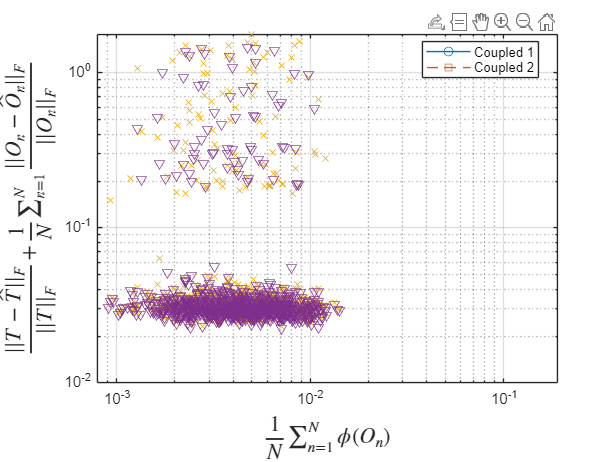



px = [0.0008 0.19];

cmap = orderedcolors("gem");

figure()

py = polyval(polyfit(covNorm(:, 3), Cost(:, 3), 1), px);
loglog(covNorm(:,3), Cost(:, 3), 'x', 'color', cmap(3, :)); hold on;
loglog(px, py, ':', 'LineWidth', 2, 'color', cmap(3, :)); hold on;


py = polyval(polyfit(covNorm(:,4), Cost(:, 4), 1), px);
loglog(covNorm(:,4), Cost(:, 4), 'v', 'color', cmap(4, :)); hold on;
loglog(px, py, '-.', 'LineWidth', 2, 'color', cmap(4, :)); hold on;

grid on; xlim(px);
ylabel("$\frac{||T - \hat{T}||_F}{||T||_F} + \frac{1}{N} \sum_{n=1}^N \frac{||O_n - \hat{O}_n||_F}{||O_n||_F}$", "Interpreter","latex",'FontSize',15,'FontWeight','bold')
xlabel("$\frac{1}{N}\sum_{n=1}^N\phi(O_n)$", "Interpreter","latex",'FontSize',15,'FontWeight','bold')

qw{1} = plot(nan, '-o', 'color', cmap(1, :));
qw{2} = plot(nan, '--s', 'color', cmap(2, :));
qw{3} = plot(nan, ':x', 'color', cmap(3, :));
qw{4} = plot(nan, '-.v', 'color', cmap(4, :)); 
legend([qw{:}], {"Coupled 1", "Coupled 2"}, 'location', 'best')